# Problem 3

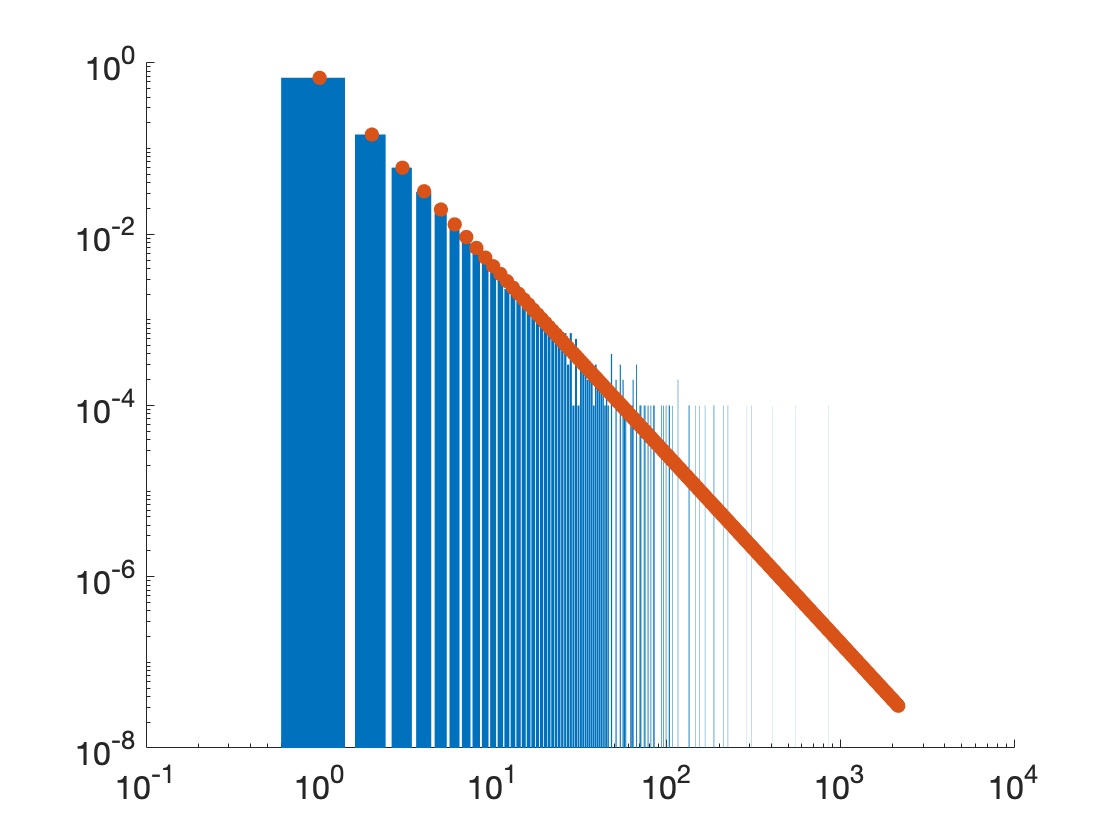

rng('default')
n = 10^4;
alpha = 2.2;
rounds = 100;
T = 0.4;

Ss = zeros(rounds,1);
infects = zeros(rounds,1);
Tcs = zeros(rounds,1);
vcs = zeros(rounds,1);

for r = 1:rounds
    % fraction of vertices in giant component
    [G,edges,K,p] = MakePowerLawRandomGraph(n,alpha);
    comps = ConnectedComponents(full(G)); 
    Ss(r) = max(comps)/n;
    % fraction of nodes affected by epidemic
    infected = randperm(length(edges),round(T*length(edges)));
    edgelist = edges(infected,:);
    sz = max(edgelist(:));
    M = sparse([edgelist(:,1);edgelist(:,2)], ...
        [edgelist(:,2);edgelist(:,1)],1,sz,sz);
    infected_nodes = ConnectedComponents(full(M));
    infects(r) = max(infected_nodes)/n;
    % critical value Tc
    k1 = 0;
    k2 = 0;
    for i = 1:length(p)
        k1 = k1 + p(i)*i;
        k2 = k2 + p(i)*i^2;
    end
    Tcs(r) = k1/(k2-k1);
    % critical fraction vc to vaccinate for T = 0.4
    kappa = k2/k1;
    vcs(r) = 1 - 1/(kappa-1);
end

avg_Ss = mean(Ss)

avg_Ss = 0.8214

avg_infects = mean(infects)

avg_infects = 0.3694

avg_Tcs = mean(Tcs)

avg_Tcs = 0.0079

avg_vcs = mean(vcs)

avg_vcs = 0.9921